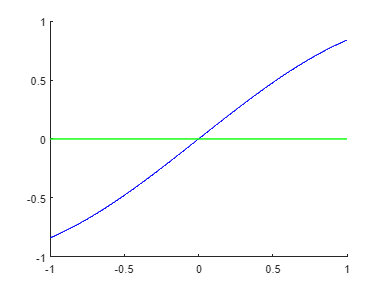

clear

startX = -1;
stepX = 0.25;
nPoints = 10;
endX = 1;
X = linspace(startX,endX,nPoints);

Y = sin(X);


P = lagrange(X, Y);
%P = newton(X, Y);
%P = polyfit(X, Y, length(X) - 1);

miniStepX = 0.001;
miniX = startX:miniStepX:endX;

F = sin(miniX);
P = polyval(P, miniX);

figure
hold on
plot(miniX, F, 'r')
plot(miniX, P, 'b')
plot(X, zeros(1, length(X)), "green")


fprintf("Max derivation: %.20f\n", deviation(X, F, P))

Max derivation: 0.00000000009369449661


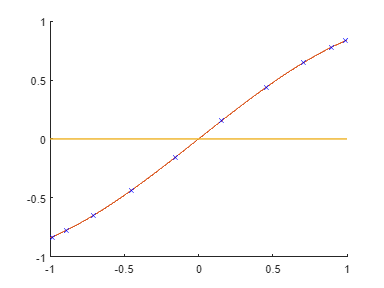



rT = chebyshevRoots(startX, endX, nPoints);

Y = sin(rT);

P = lagrange(rT, Y);
%P = newton(rT, Y);
%P = polyfit(X, Y, length(X) - 1);

miniStepX = 0.001;
miniX = startX:miniStepX:endX;

F = sin(miniX);
P = polyval(P, miniX);

figure
hold on
plot(miniX, F)
plot(miniX, P)
plot(X, zeros(1, length(X)));
plot(rT, Y, "bx")


fprintf("Max derivation: %.20f\n", deviation(miniX, F, P))

Max derivation: 0.00000000004782896301
